Task 1.1

%creating the signal
N = 1000;
fs = 1000;
t = (0:N-1)/fs; % time range
f1 = 30;
a1 = 1;
%creating signal
y = a1*sin(2*pi*f1*t);

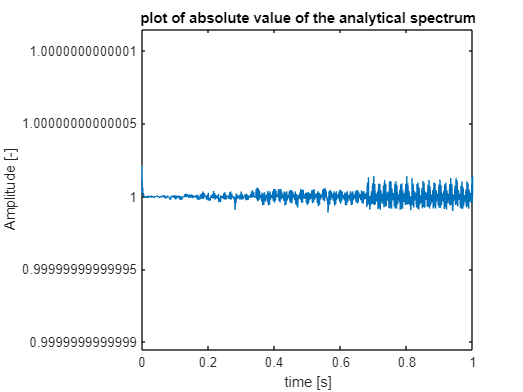

%calculating hilbert transform of the sine wave
yh = hilbert(y);
%plotting absolute value of the spectrum
figure()
plot(t,abs(yh))
xlabel('time [s]')
ylabel('Amplitude [-]')
title('plot of absolute value of the analytical spectrum')

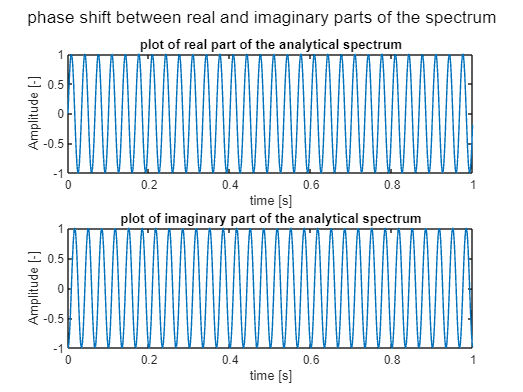

%comparing real vs imaginary part of the analytical spectrum
figure()
subplot(2,1,1)
plot(t,real(yh))
xlabel('time [s]')
ylabel('Amplitude [-]')
ylim([-1,1])
title('plot of real part of the analytical spectrum')
subplot(2,1,2)
plot(t,imag(yh))
xlabel('time [s]')
ylabel('Amplitude [-]')
ylim([-1,1])
title('plot of imaginary part of the analytical spectrum')
sgtitle('phase shift between real and imaginary parts of the spectrum')

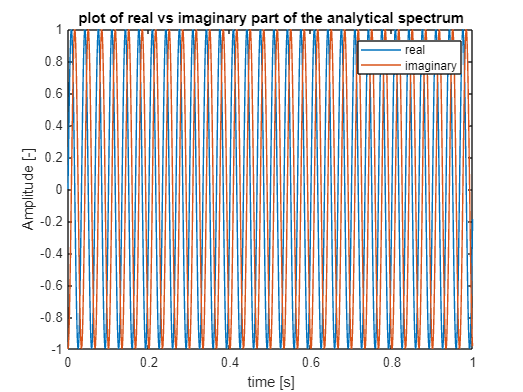

%checking phase shift
figure()
plot(t,real(yh)), hold on
plot(t,imag(yh)), hold off
legend('real','imaginary')
xlabel('time [s]')
ylabel('Amplitude [-]')
ylim([-1,1])
title('plot of real vs imaginary part of the analytical spectrum')

%calculating time shift
dt=0.35-0.342; %[s]
T=1/f1;
dphi1 = 360*dt/T 

dphi1 = 86.4000

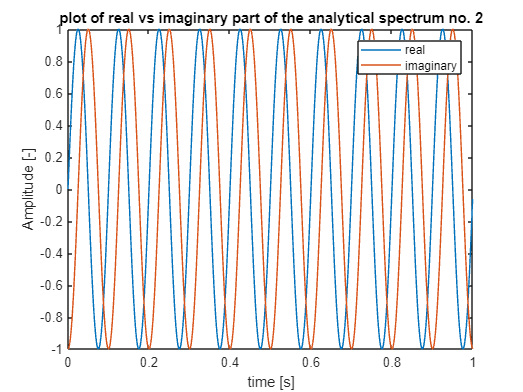

%recalculating phase shift ofor a different frequency
f2 = 10;
y2 = a1*sin(2*pi*f2*t);
%calculating hilbert transform of the sine wave
yh2 = hilbert(y2);
%plotting absolute value of the spectrum
%checking phase shift
figure()
plot(t,real(yh2)), hold on
plot(t,imag(yh2)), hold off
legend('real','imaginary')
xlabel('time [s]')
ylabel('Amplitude [-]')
ylim([-1,1])
title('plot of real vs imaginary part of the analytical spectrum no. 2')

%calculating time shift
dt2=0.35-0.325; %[s]
T2=1/f2;
dphi2 = 360*dt2/T2 

dphi2 = 90.0000

The shift between the real and imaginary parts of the signal will always be 90 deg due to the decomposition of the signal into sine and cosine waves which have a 90 deg phase shift between each other. We got 86 deg in the 1st one due to the sampling frequency being too low, we could solve this issue by increasing sampling frequency or by taking an average of multiple periods.

Task 2

N = 2000; %2000 samples
Fs = 2000; %converting 2kHz into Hz
T = (0:N-1)/Fs; % time range
F0 = 5; %Hz
F1 = 200; %Hz
T1 = 1;
Y = chirp(T,F0,T1,F1, 'linear' );
h = hann(N);
y = Y.*h';

Task 2.1

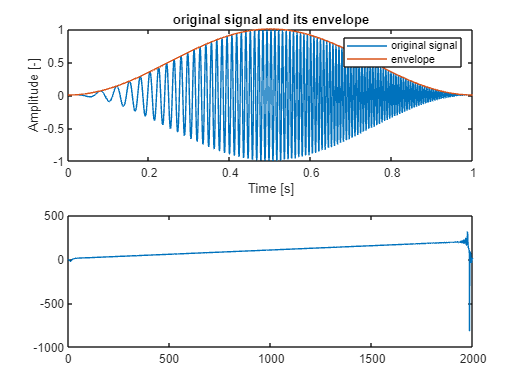

%computing analytical spectrum
yh = hilbert(y);
%computing phase of the signal
phase = angle(yh);
%unwrapping phase
phase_unwrap = unwrap(phase);
%calculating the derivative
dphase = diff(phase_unwrap);
%scaling the derivative to get instantenuous frequency
inst_freq = dphase*Fs/(2*pi);
%plotting the results
figure()
subplot(2,1,1)
plot(T, y), hold on
plot(T, abs(yh)), hold off
xlabel('Time [s]')
ylabel('Amplitude [-]')
legend('original signal','envelope')
title('original signal and its envelope')
subplot(2,1,2)
plot(inst_freq)

Task 2.2

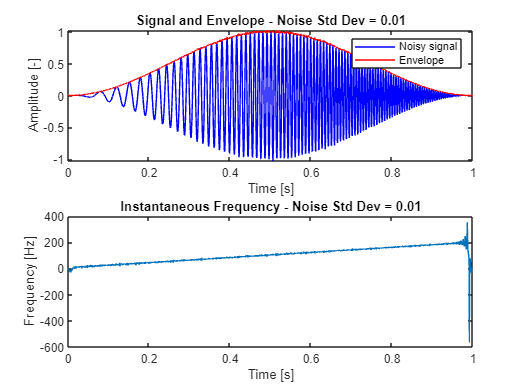

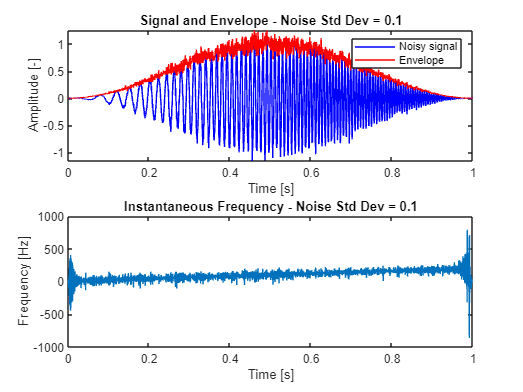

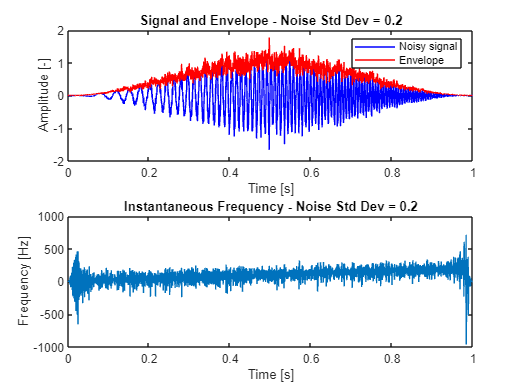

% Parameters
N = 2000; % Number of samples
Fs = 2000; % Sampling frequency in Hz
T = (0:N-1)/Fs; % Time vector
F0 = 5; % Initial frequency in Hz
F1 = 200; % Final frequency in Hz
T1 = 1; % Duration in seconds

% Generate the chirp signal
Y = chirp(T, F0, T1, F1, 'linear');

% Hann window
h = hann(N)';

% Add Gaussian noise with different standard deviations
noise1 = 0.01 * randn(N, 1)';
noise2 = 0.1 * randn(N, 1)';
noise3 = 0.2 * randn(N, 1)';

% Add noise to the signal
Y_noise1 = Y + noise1;
Y_noise2 = Y + noise2;
Y_noise3 = Y + noise3;

% Windowing the noisy signals
y1 = Y_noise1 .* h;
y2 = Y_noise2 .* h;
y3 = Y_noise3 .* h;

% Compute the analytical spectrum, envelope, and instantaneous frequency for each noisy signal
noisy_signals = {y1, y2, y3};
titles = {'Noise Std Dev = 0.01', 'Noise Std Dev = 0.1', 'Noise Std Dev = 0.2'};

for i = 1:3
    % Current noisy signal
    y_current = noisy_signals{i};
    
    % Analytical signal (Hilbert transform)
    yh = hilbert(y_current);
    
    % Compute envelope
    envelope = abs(yh);
    
    % Compute phase
    phase = angle(yh);
    
    % Unwrap phase
    phase_unwrap = unwrap(phase);
    
    % Calculate the derivative of the unwrapped phase
    dphase = diff(phase_unwrap);
    
    % Scale the derivative to get the instantaneous frequency
    inst_freq = dphase * Fs / (2 * pi);
    
    % Plot the results in a separate figure for each noise level
    figure;
    
    % Plot the noisy signal and its envelope
    subplot(2, 1, 1);
    plot(T, y_current, 'b', T, envelope, 'r');
    xlabel('Time [s]');
    ylabel('Amplitude [-]');
    legend('Noisy signal', 'Envelope');
    title(['Signal and Envelope - ', titles{i}]);
    
    % Plot the instantaneous frequency
    subplot(2, 1, 2);
    plot(T(1:end-1), inst_freq);
    xlabel('Time [s]');
    ylabel('Frequency [Hz]');
    title(['Instantaneous Frequency - ', titles{i}]);
end

Task2.3

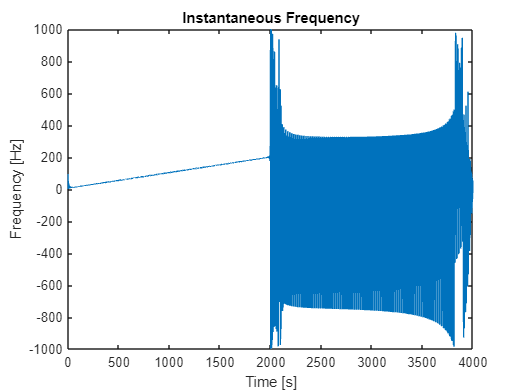

y_sin = 0.1*T.*sin(2*pi*T*100) + 0.1*T.*sin(2*pi*T*500);
y2 = zeros(1,4000);
y2(1:2000)=Y;
y2(2001:4000)=y_sin;
%computing analytical spectrum
yh = hilbert(y2);
%computing phase of the signal
phase = angle(yh);
%unwrapping phase
phase_unwrap = unwrap(phase);
%calculating the derivative
dphase = diff(phase_unwrap);
%scaling the derivative to get instantenuous frequency
inst_freq = dphase*Fs/(2*pi);
%plotting the results
figure()
plot(inst_freq)
xlabel('Time [s]');
ylabel('Frequency [Hz]');
title('Instantaneous Frequency');

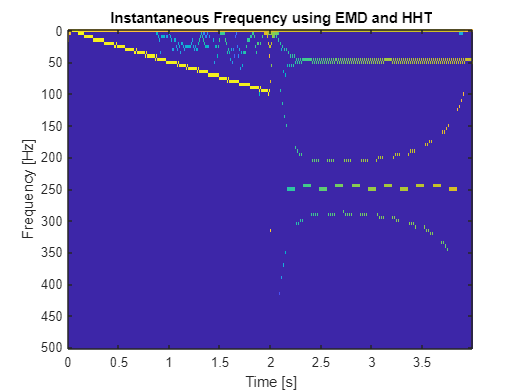

[imf,residual] = emd(y2);
[dat,freq,time] = hht(imf,fs, 'FrequencyLimits' ,[0 500]);
figure()
imagesc(time,freq,log(dat))
xlabel('Time [s]');
ylabel('Frequency [Hz]');
title('Instantaneous Frequency using EMD and HHT');

Task4

% Model coefficients
m1 = 1;
c1 = 100;
k1 = 1e6;
damping_coefficient = c1 / (2 * sqrt(k1 * m1));

% Natural frequency of the system
fc = sqrt(k1 / m1) / (2 * pi);

% Transmittance of the system
sys = tf(1, [m1 c1 k1]);
fs = 1e4;
t = 0:1/fs:0.05;
s = length(t);

% Impulse response of the signal
y = impulse(sys, t);
y = y + 5e-5 * randn(s, 1);

%% 1. CALCULATE THE ENVELOPE OF THE Y SIGNAL
analytic_signal = hilbert(y);
up = abs(analytic_signal);

%% 2. CALCULATE THE LOGARITHM OF THE ENVELOPE, SCALE IN DB
log_env = 20 * log10(up);

%% 3. SMOOTH THE LOGARITHM OF THE ENVELOPE USING MOVING AVERAGE
window_size = 100; % Adjust the window size as needed
smoothed_log_env = movmean(log_env, window_size);

% Fit a polynomial (e.g., order 4) to the smoothed envelope
p = polyfit(t, smoothed_log_env, 4);
EnvFit = polyval(p, t);

%% 4. FIND THE TIME CONSTANT FROM EnvFit GRAPH (based on -8.7 dB amplitude change)
% Target dB drop
target_dB_drop = -8.7;

% Find the time constant τ based on the point where EnvFit drops by -8.7 dB
[~, idx] = min(abs(EnvFit - target_dB_drop));
tau = t(idx);

%% 5. CALCULATE THE DAMPING FACTOR FROM THE TIME CONSTANT
% The damping factor ζ is related to the time constant τ by:
% τ = 1 / (ζ * ω_n), where ω_n is the natural frequency in rad/s
omega_n = 2 * pi * fc;
damping_factor = 1 / (0.0224 * omega_n);

% Display results
disp(['Calculated damping factor: ', num2str(damping_factor)]);

Calculated damping factor: 0.044643


disp(['Theoretical damping factor: ', num2str(damping_coefficient)]);

Theoretical damping factor: 0.05


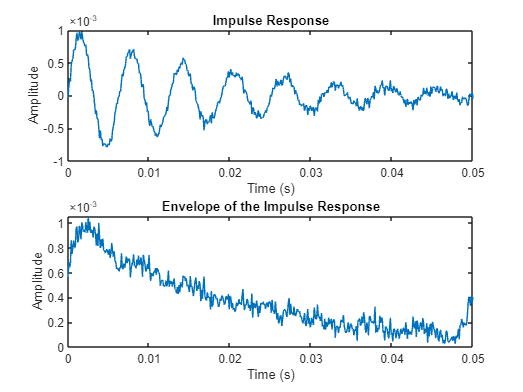


%% Plot graphs
figure;
subplot(2,1,1);
plot(t, y);
title('Impulse Response');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, up);
title('Envelope of the Impulse Response');
xlabel('Time (s)');
ylabel('Amplitude');

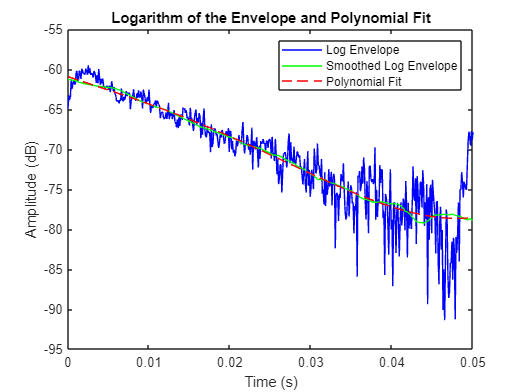


figure()
plot(t, log_env, 'b', t, smoothed_log_env, 'g', t, EnvFit, 'r--');
title('Logarithm of the Envelope and Polynomial Fit');
xlabel('Time (s)');
ylabel('Amplitude (dB)');
legend('Log Envelope', 'Smoothed Log Envelope', 'Polynomial Fit');